# Using Matlab in Linear Algebra

## 1) Write a simple command to create the following scalar, vectors and arrays

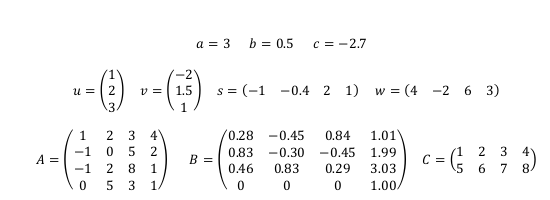

a = 3

a = 3

b = 0.5

b = 0.5000

c = -2.7

c = -2.7000

u = [1 2 3]'

u =      1
     2
     3


v = [-2 1.5 1]'

v =    -2.0000
    1.5000
    1.0000


s = [-1 -0.4 2 1]

s =    -1.0000   -0.4000    2.0000    1.0000


w = [4 -2 6 3]

w =      4    -2     6     3


A = [1 2 3 4; -1 0 5 2; -1 2 8 1; 0 5 3 1]

A =      1     2     3     4
    -1     0     5     2
    -1     2     8     1
     0     5     3     1


B = [0.28 -0.45 0.84 1.01; 0.83 -0.30 -0.45 1.99; 0.46 0.83 0.29 3.03; 0 0 0 1]

B =     0.2800   -0.4500    0.8400    1.0100
    0.8300   -0.3000   -0.4500    1.9900
    0.4600    0.8300    0.2900    3.0300
         0         0         0    1.0000


C = [1 2 3 4; 5 6 7 8]

C =      1     2     3     4
     5     6     7     8


## 3) Write commands to carry out the following operations (check and analyze the operation’s result)

### u+v

u + v

ans =    -1.0000
    3.5000
    4.0000


### u-v

u - v

ans =     3.0000
    0.5000
    2.0000


### conjugate transpose of vector u

u'

ans =      1     2     3


### a*v

a * v

ans =    -6.0000
    4.5000
    3.0000


### u*v

% u * v

Result is incorrect since the symbol '*' does the matrix multiplication, and the matrixes used don't comply the requisites of having the same number of columns as rows of the other one.

### u.*v

u .* v

ans =     -2
     3
     3


This operation works correctly since it's an element-by-element multiplication

### u*v’

u * v'

ans =    -2.0000    1.5000    1.0000
   -4.0000    3.0000    2.0000
   -6.0000    4.5000    3.0000


In this time, the matrix multiplication is correctly applied, since we transposed v to comply the matrix multiplication requisites.

### dot product of vectors u and v

u .* v

ans =     -2
     3
     3


### cross product of vectors u and v

cross(u,v)

ans =    -2.5000
   -7.0000
    5.5000


### dot product of vectors s and w

s .* w

ans =    -4.0000    0.8000   12.0000    3.0000


### cross product of vectors w and w

% cross(w, w)

This calculus won't work since the cross product is made to points, defined by 3 elements. We can use multiple points, and so the matrixes used can be multiples of 3. In this case it isn't.

### transpose of matrix A

A'

ans =      1    -1    -1     0
     2     0     2     5
     3     5     8     3
     4     2     1     1


### inverse of matrix A

inv(A)

ans =     0.5408   -1.1939    0.7347   -0.5102
   -0.0612    0.0408   -0.1020    0.2653
    0.0714   -0.2143    0.2857   -0.1429
    0.0918    0.4388   -0.3469    0.1020


### A+B

A+B

ans =     1.2800    1.5500    3.8400    5.0100
   -0.1700   -0.3000    4.5500    3.9900
   -0.5400    2.8300    8.2900    4.0300
         0    5.0000    3.0000    2.0000


### A-B

A-B

ans =     0.7200    2.4500    2.1600    2.9900
   -1.8300    0.3000    5.4500    0.0100
   -1.4600    1.1700    7.7100   -2.0300
         0    5.0000    3.0000         0


### matrix multiplication of A and B

A * B

ans =     3.3200    1.4400    0.8100   18.0800
    2.0200    4.6000    0.6100   16.1400
    5.0600    6.4900    0.5800   28.2100
    5.5300    0.9900   -1.3800   20.0400


### array multiplication of A and B

A .* B

ans =     0.2800   -0.9000    2.5200    4.0400
   -0.8300         0   -2.2500    3.9800
   -0.4600    1.6600    2.3200    3.0300
         0         0         0    1.0000


### matrix multiplication of A and C

% A * C

Like explained before, A's columns need to be the same size of C rows.

### matrix multiplication of C and A

C * A

ans =     -4    28    49    15
    -8    64   125    47


### array multiplication of A and C

% A .* C

To do the array multiplication element-by-element, the dimensions of both matrixes need to be the same.

### array multiplication of C and A

% C .* A

Like th last one, to do the array multiplication element-by-element, the dimensions of both matrixes need to be the same.

### w*A

w * A

ans =      0    35    59    21


### A*w

% A * w

Like explained before, A's columns need to be the same size of w rows.

## 4) Write commands to extract the given element or submatrix of a given matrix

### extract cell (2,4) of matrix A

A(2,4)

ans = 2

### extract row 2 of matrix A

A(2,:)

ans =     -1     0     5     2


### extract column 4 of matrix B

B(:,4)

ans =     1.0100
    1.9900
    3.0300
    1.0000


### to extract 3x3 submatrix from the three first rows and three first column of B.

B(1:3,1:3)

ans =     0.2800   -0.4500    0.8400
    0.8300   -0.3000   -0.4500
    0.4600    0.8300    0.2900


## 5) Generate some “special” matrix using commands zeros, ones, eye, rand, radn, and magic. Analyze results.

### zeros

zeros(5)

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Creates 5x5 array of zeros.

### ones

ones(5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


Creates 5x5 array of ones.

### eye

eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Creates the Identity matrix of size 4.

### rand

rand(4)

ans =     0.2769    0.6948    0.4387    0.1869
    0.0462    0.3171    0.3816    0.4898
    0.0971    0.9502    0.7655    0.4456
    0.8235    0.0344    0.7952    0.6463


Creates 4x4 array of random numbers.

### magic

magic(4)

ans =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


Creates 4x4 array which the sum of the elements in each column and the sum of the elements in each row are the same.

## 6) Write commands to obtain eigenvalues and eigenvectors of matrix A and matrix B (check and analyze the operation’s result). If necessary read about the meaning of eigenvalues and eigenvectors.

eig(A)

ans =     9.0909
   -3.1380
    2.8355
    1.2115



eig(B)

ans =    0.9909 + 0.0000i
  -0.3605 + 0.9248i
  -0.3605 - 0.9248i
   1.0000 + 0.0000i


The eig() function return an eigenvector which contains the eigenvalues of the provided matrix. 

The eigenvectors of a matrix are a set of values that if operated by its matrix or multiplied by an scalar will never change its direction.

## 7) Systems of Linear Equations

a = [2 -1 3; 1 2 2; -1 5 -2]

a =      2    -1     3
     1     2     2
    -1     5    -2


b = [11.5; 6; -9.5]

b =    11.5000
    6.0000
   -9.5000



X = a \ b

X =     1.0000
   -0.5000
    3.0000
